# 2.Training models using transfer learning

In this lesson, we will learn how to train an object detection model using transfer learning. These techniques reduce computational effort and improve model performance, even with small datasets.

First, we add the help module:

addpath('help-module');

## Training

### **Required YOLO Parameters**

The following parameters are mandatory when configuring a YOLO training session:

- **configFile **(str)**: **Path to the configuration file (usually in `.yaml` format) that defines the dataset structure and classes. This file should include paths to training, validation, and optional test sets, as well as the list of class names. As an example the file we will use in this tutorial is data.yaml which already contains all the defined structure.

- **baseModel **(str): This parameter specifies which model will be used for training. It allows you to either continue training a previously trained model or start training from a pre-trained YOLO model.You can choose among different YOLO versions, tasks (e.g., object detection, segmentation, classification), and model sizes. For these tutorials, we will use **YOLOv8 for object detection**. The available pre-trained models, ordered from smallest to largest, are: yolov8n.pt, yolov8s.pt, yolov8m.pt, yolov8l.pt, yolov8x.pt. It is recommended in these lessons to use smaller models (e.g., `yolov8n.pt` or `yolov8s.pt`) for faster training and inference speed.

- `MaxEpochs ``(int): This parameter `sets the maximum number of epochs for training, where an epoch is one complete pass over all the images in the training dataset. Increasing this value usually improves model performance but also extends training time.

- `ImageSize ``(list[int]): `The size (in pixels) that all images will be resized to before training. Larger sizes may improve accuracy but require more computational resources.

In the following code, we define the values for these required parameters. Use these parameters to speed up execution:

configFile = fullfile(pwd, 'datasets', 'fruits_3_4998', 'data.yaml');
baseModel = 'yolov8s-oiv7.pt';
options.MaxEpochs = 1;
options.ImageSize = [256 256 3];

### YOLO layers visualization

The following code allows you to visualize the architecture and parameters of a YOLOv8 model:

det = yolov8ObjectDetector2('yolov8s');

% Analyze loaded model
analyzeNetwork(det.Network);

This command opens a new window displaying all the layers and parameters of the YOLO model being used. Keep in mind that different YOLOv8 variants (e.g., `yolov8s`, `yolov8m`, etc.) differ not only in the number of parameters but also slightly in their architectural complexity.

In the case of YOLOv8, the model typically consists of 23 main blocks. These can be grouped into three main components:

- **Backbone (first 10 blocks):** Responsible for extracting features from the input image.

- **Neck (next 12 blocks):** Combines features at different scales to enhance detection performance.

- **Head (last block):** Responsible for predicting bounding boxes, class labels, and confidence scores.

### **Freezing Layer Parameter for Transfer Learning**

One of the main advantages of YOLO models is that they come **pre-trained**. Training an object detection model from scratch usually requires millions of images and considerable computational power. This problem can be solved using **transfer learning**, which involves taking a model that has already been trained on a large dataset and slightly retraining it using a much smaller set of new data.

**Transfer learning** is particularly effective in computer vision because convolutional neural networks (CNNs), which are the foundation of YOLO (and all object detection models), learn features in a **hierarchical** manner. The initial layers detect low-level features such as edges and textures, while deeper layers capture more complex patterns and object structures. This hierarchy makes the early layers highly reusable across different tasks.

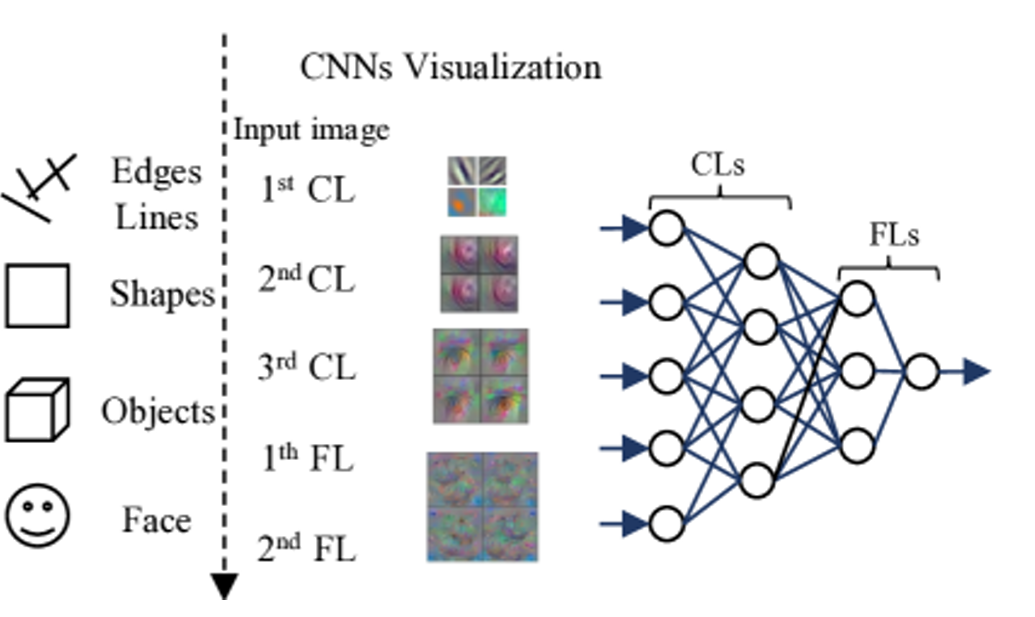

Typically, the early layers responsible for feature extraction (the **backbone) **are **frozen** during training, meaning their weights are not updated. This allows the model to retain the general visual features learned from large datasets. Meanwhile, the later layers are **fine-tuned** on the new dataset to adapt to the specific task at hand.

In some scenarios, the entire model may be fine-tuned using a **lower learning rate**, allowing it to gradually adapt to the new data while minimizing the risk of overwriting valuable pre-trained knowledge.

This is why we use YOLOv8. It comes pre-trained on large datasets such as [**COCO**](https://docs.ultralytics.com/es/datasets/detect/coco/) (e.g., `yolov8n.pt`, `yolov8s.pt`) or [**Open Image V7**](https://docs.ultralytics.com/es/datasets/detect/open-images-v7/#open-images-v7-pretrained-models)  (e.g., `yolov8n-oiv7.pt`, `yolov8s-oiv7.pt`). Using these models significantly reduces training time and improves performance, even with smaller datasets.

#### Choosing which layers to freeze

The choice of how many YOLOv8 layers to freeze depends on how similar your target dataset is to the pretrained data. YOLOv8 has 22 freeze-able layers: the first 10 extract generic features (edges, textures, shapes), while later layers specialize in detection. Since our classes (apple, orange, pear) are well represented in COCO and Open Images V7, the domains closely match. This allows us to freeze most layers to keep general features intact and fine-tune only the higher-level layers for our fruits, which speeds training and lowers overfitting risk.

To freeze specific layers during training, we use the `freeze` parameter  as follows:

optionalArgs = {'freeze', 15};

Pretrained yolov8s network already exists.



**There are additional parameters available to configure the model, which will be explained in Lesson 4: Experimentation.**

### Starting training

Next, we train the YOLO model with the parameters we defined earlier. This may take approximately 2 minutes.

[yolov8Det, results] = trainYOLOv8ObjectDetector( ...
    configFile, ...
    baseModel, ...
    options, ...
    optionalArgs{:});

### Continue a train

If the training process is interrupted for any reason, it can be resumed using the `resume` option. This feature loads the weights from the last saved model and also restores the optimizer state, learning rate scheduler, and epoch number. This allows you to continue the training process seamlessly from where it was left off.

For more details, refer to the **Resume Training** section in the official  [documentation](https://docs.ultralytics.com/modes/train/#resuming-interrupted-trainings).

### Retrain a model

Alternatively, you can continue training an already trained model by using it as a starting point instead of a base model like `yolov8n.pt` or `yolov8s.pt`. In this case, you simply load the weights from the previously trained model.

However, unlike the `resume` option, this approach **does not** restore the optimizer state, learning rate schedule, or epoch number. These parameters are reset, and training starts from epoch 1 with the current training options.

This method is useful when you want to fine-tune a model further or adapt it to a new dataset, but without continuing exactly where the previous training left off.

### Load a model

When training a YOLO model, the trained weights are typically saved in the `runs/detect/train@/weights` directory, where `@` is an incrementing counter (e.g., `train1`, `train2`, etc.) to avoid overwriting previous runs.

If this folder is not created, it is likely that the YOLO settings were not properly configured during the **1. Installation.mlx** step. To resolve this, re-run that section and ensure everything is correctly set up.

Inside the `weights` folder, you’ll find several model files, including `last.pt`, `best.pt`, and `best.onnx`. The function `utils.loadModel` always loads the `best.onnx` model from the selected folder.

Therefore, in the following code, you should load the model from the first training run:

modelPath = fullfile(pwd, 'runs', 'detect', 'first', 'weights');
configFile = fullfile(pwd, 'datasets', 'fruits_3_4998', 'data.yaml');

yolov8Det = utils.loadModel(modelPath, configFile);

## Prediction

In this section, we use the model we trained earlier to detect fruits in the following images.

utils.detectAndDisplayImage(yolov8Det, 'pear.jpg'); 

utils.detectAndDisplayImage(yolov8Det, 'apple.jpg');

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python.exe"
          Library: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python311.dll"
             Home: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python"
           Status: Terminated
    ExecutionMode: OutOfProcess


False
is instance freeze
New https://pypi.org/project/ultralytics/8.3.174 available 😃 Update with 'pip install -U ultralytics'
Ultralytics YOLOv8.2.66 🚀 Python-3.11.5 torch-2.7.0+cpu CPU (11th Gen Intel Core(TM) i5-1135G7 2.40GHz)
□□engine\trainer: □task=detect, mode=train, model=yolov8s-oiv7.pt, data=C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\datasets\fruits_3_4998\data.yaml, epochs=1, time=None, patience=100, batch=16, imgsz=256, save=True, save_period=-1, cache=False, device=None, workers=8, project=None, name=first, exist_ok=False, pretrained=True, optimizer=auto, verbose=True, seed=0, deterministic=True, single_cls=False, rect=False, cos_lr=False, close_mosaic=10, resume=False, amp=True, fraction=1.0, profile=False, freeze=15, multi_scale=False, overlap_mask=True, mask_ratio=4, dropout=0.0, val=True, split=val, save_json=False, save_hybrid=False, conf=None, iou=0.7, max_det=300, half=False, dnn=False, plots=True, source

Overriding model.yaml nc=601 with nc=3

                   from  n    params  module                                       arguments                     
  0                  -1  1       928  ultralytics.nn.modules.conv.Conv             [3, 32, 3, 2]                 
  1                  -1  1     18560  ultralytics.nn.modules.conv.Conv             [32, 64, 3, 2]                
  2                  -1  1     29056  ultralytics.nn.modules.block.C2f             [64, 64, 1, True]             
  3                  -1  1     73984  ultralytics.nn.modules.conv.Conv             [64, 128, 3, 2]               
  4                  -1  2    197632  ultralytics.nn.modules.block.C2f             [128, 128, 2, True]           
  5                  -1  1    295424  ultralytics.nn.modules.conv.Conv             [128, 256, 3, 2]              
  6                  -1  2    788480  ultralytics.nn.modules.block.C2f             [256, 256, 2, True]           
  7                  -1  1   1180672  ultralytic

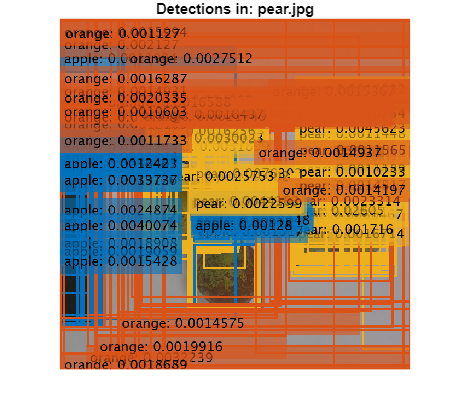

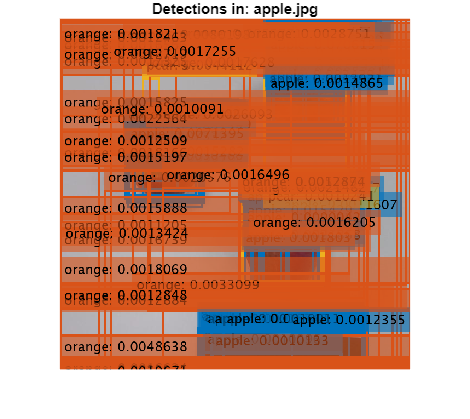

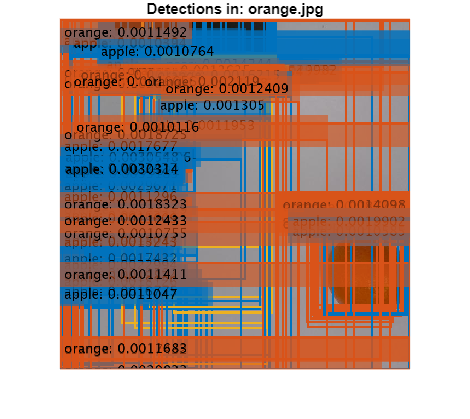

utils.detectAndDisplayImage(yolov8Det, 'orange.jpg');

As observed in the results, the model produces an excessive number of detections, leading to a low-precision output.

We will discuss this topic in detail in the next lesson.